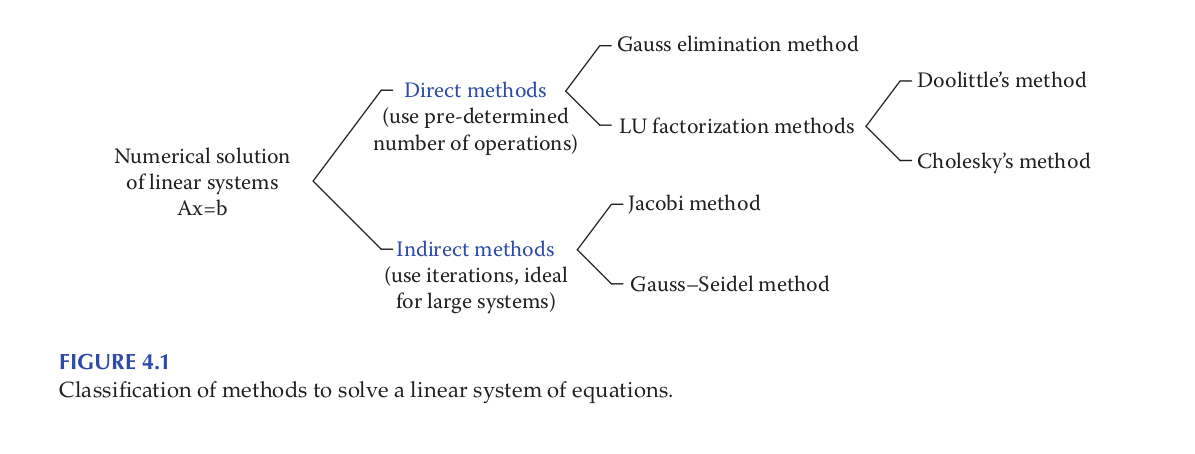

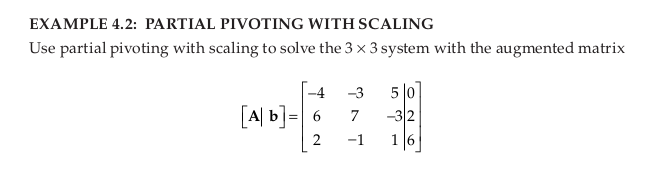

A = [-4 -3 5;6 7 -3;2 -1 1]; 
b = [0;2;6];

x = GaussPivotScale(A,b)

x =      2
    -1
     1


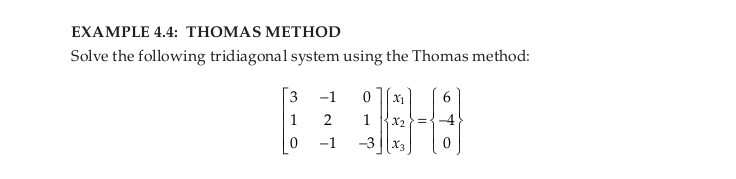

clc;clear;  
A = [3 -1 0;1 2 1;0 -1 -3]; 
b = [6;-4;0];
x = ThomasMethod(A,b)

x =    1.000000000000000
  -3.000000000000000
   1.000000000000000


Matlab Buit-in Function

x = A\b

x =    1.000000000000000
  -3.000000000000000
   1.000000000000000


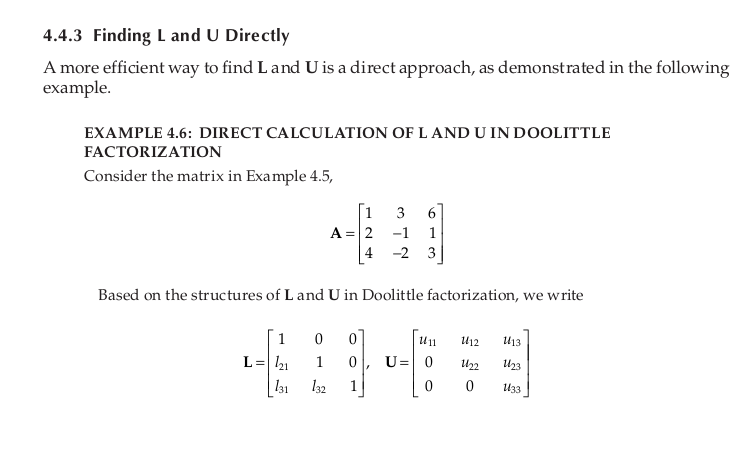

clear;clc;
A = [1 3 6;2 -1 1;4 -2 3];
[L, U] = DoolittleFactor(A)

L =      1     0     0
     2     1     0
     4     2     1


U =      1     3     6
     0    -7   -11
     0     0     1


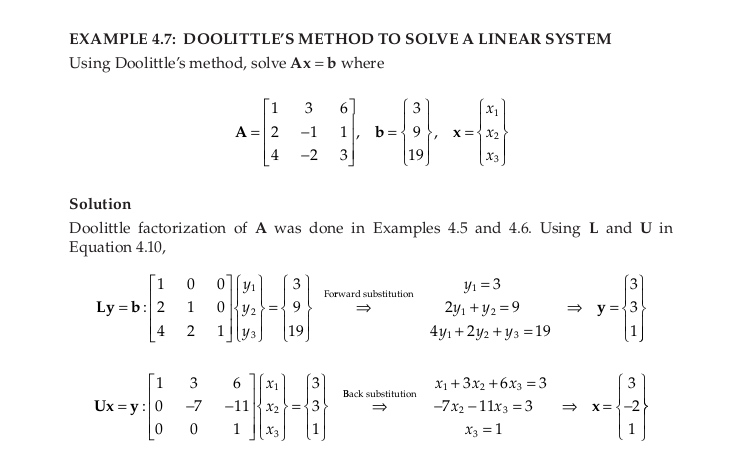

A = [1 3 6;2 -1 1;4 -2 3]; 
b = [3;9;19];
x = DoolittleMethod(A,b)

x =      3
    -2
     1


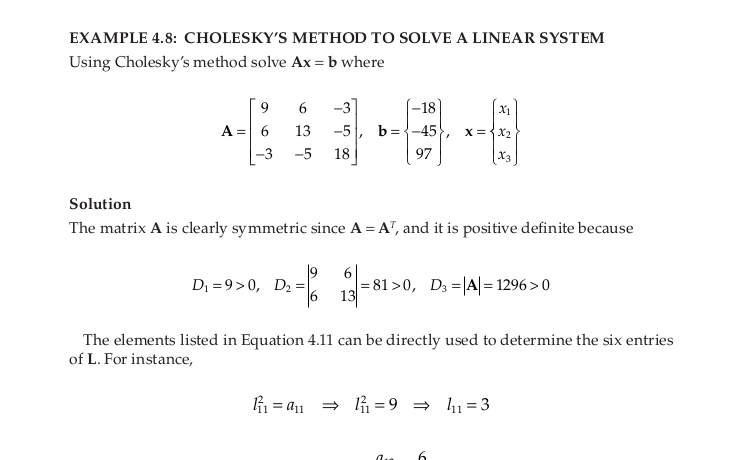

clc;clear;
A = [9 6 -3;6 13 -5;-3 -5 18]; 
b = [-18;-45;97];
x = CholeskyMethod(A,b)

x =      1
    -2
     5


Built-in function

A = [4 -1 0;-1 3 -5;2 5 6];
[L,U,P] = lu(A)

L =    1.000000000000000                   0                   0
   0.500000000000000   1.000000000000000                   0
  -0.250000000000000   0.500000000000000   1.000000000000000


U =    4.000000000000000  -1.000000000000000                   0
                   0   5.500000000000000   6.000000000000000
                   0                   0  -8.000000000000000


P =      1     0     0
     0     0     1
     0     1     0


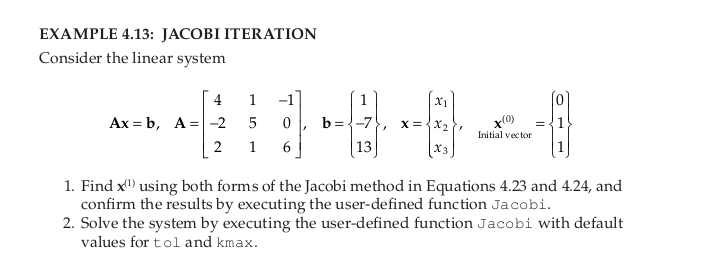

A = [4 1 -1;-2 5 0;2 1 6]; 
b = [1;-7;13]; 
x0 = [0;1;1];
x = Jacobi(A, b, x0, [], 1)

x =    0.250000000000000
  -1.400000000000000
   2.000000000000000


[x, k, MJnorm] = Jacobi(A, b, x0) % Default values for tol and kmax

x =    0.999972708724494
  -0.999976111805555
   1.999968745156036


k =     13


MJnorm =    0.500000000000000


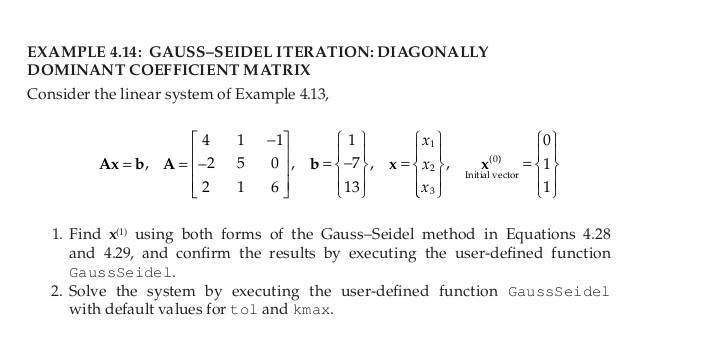

clear;
clc;
A = [4 1 -1;-2 5 0;2 1 6]; b = [1;-7;13]; x0 = [0;1;1];
x = GaussSeidel(A, b, x0, [], 1)

x =    0.250000000000000
  -1.300000000000000
   2.300000000000000


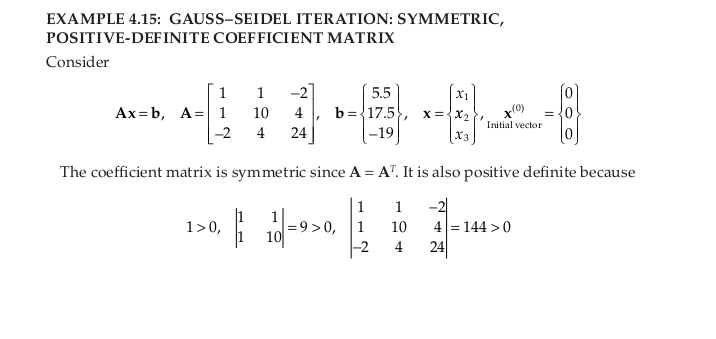

A = [1 1 -2;1 10 4;-2 4 24]; 
b = [5.5;17.5;-19];
[x, k, MGSnorm] = GaussSeidel(A, b)

x =    1.500042808914387
   1.999991157725251
  -0.999994958878010


k =     15


MGSnorm =      3


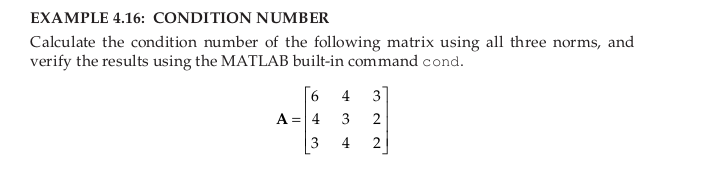

clear;clc;
A = [6 4 3;4 3 2;3 4 2];
[cond(A,1), cond(A,inf), cond(A,'fro')] % Using three different matrix norms

ans = 1.0e+02 *

   2.469999999999999   2.729999999999999   1.657980699525781
